Import raw data

addpath('path_to_PBLR')
iniData = readtable('raw.txt','Delimiter','\t','ReadRowNames',true,...
    'ReadVariableNames',true);

Preprocessing data

minGenes = 0; minCells = 0; libararyflag = 0; logNormalize = 1;  
proData = preprocessing(iniData, minCells, minGenes, libararyflag,logNormalize);
M = proData.data;

Select informative genes used for clustering

id = gene_selection(M);

Clustering

M0 = M(id,:);
K = 3;
numCores = 3;
[group,coph] = clusteing(M0,K,numCores);

INMF:1
INMF:3
INMF:7
INMF:2
INMF:6
INMF:5
INMF:4
INMF:11
INMF:10
INMF:9
INMF:8
INMF:14
INMF:13
INMF:12
INMF:16
INMF:15
INMF:19
INMF:18
INMF:17
INMF:20


Select boundary function through visualizing. 

The boundary functions are divided into three categories:

1: exponetial function; 

2: simple piecewise function;

3: sophisticated piecewise function.

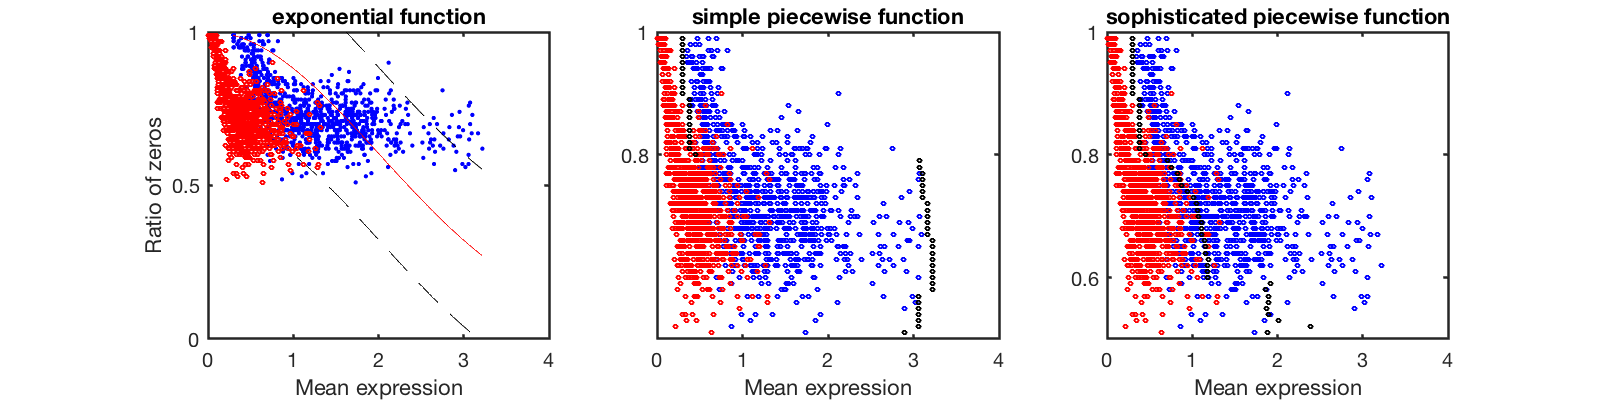

boundary_selection(M);

Run PBLR with selected boundary function

boundary_function = 3;
imputation_all = true;
accelate = true;
tic;
X = PBLR_main(M,id,group,boundary_function,imputation_all,numCores,accelate);

Imputing the submatrix of selected genes across cells of each cluster: 
Imputing the remaining submatrix: 


toc;

Elapsed time is 2.318765 seconds.


Export the imputed matrix

if isequal(imputation_all,true)
    id = 1:size(M,1);
end
T = array2table(X,'VariableNames',proData.cells,'RowNames',proData.genes(id));
writetable(T,'PBLR_impute.txt','Delimiter','\t','WriteRowNames',1);